function model = generate_non_gaussian_sequence(lambda, samples)

    % Gaussian white noise
    g1 = randn(samples,1);  
    g2 = randn(samples,1);

    % Non-Gaussian multiplicative model
    model = g1 .* exp(lambda * g2 - lambda^2);
end

function cascade = generate_cascade(cascade_steps, samples, lambda)

    if nargin < 1 || cascade_steps == -1
        cascade_steps = floor(log2(samples));   % full cascade
    end
    if nargin < 2
        samples = 2^15;
    end
    if nargin < 3
        lambda = 0.1;
    end



    % Start with Gaussian white noise (lambda = 0)
    cascade = generate_non_gaussian_sequence(0, samples);

    for step = 0:(cascade_steps-1)
        interval_len = floor(samples / 2^step);

        for interval_index = 0:(2^step - 1)

            idx1 = interval_index * interval_len + 1;
            idx2 = (interval_index + 1) * interval_len;

            % Lognormal multiplier
            multiplier = exp(lambda * randn(1) - lambda^2);

            % Apply multiplicative weight
            cascade(idx1:idx2) = cascade(idx1:idx2) * multiplier;
        end
    end
end

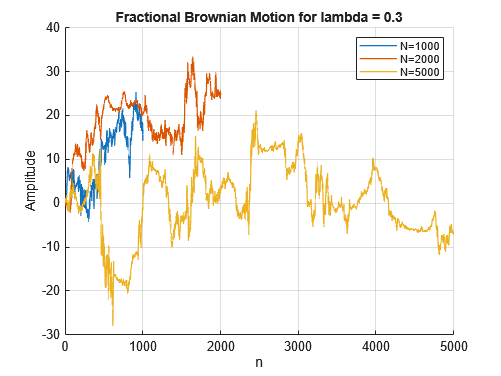

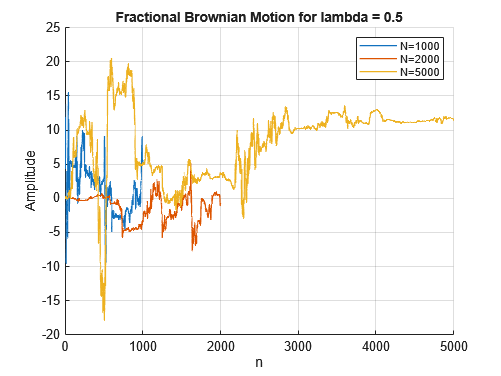

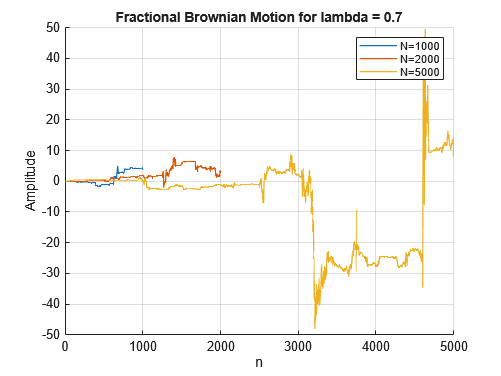

clear; close all; clc;
warning('off','MATLAB:plot:IgnoreImaginaryXYPart')

%% ---------------------------------------------------------
% PARAMETERS
% ---------------------------------------------------------
lambda  = [0.3, 0.5, 0.7];                 % lambda
Nvals  = [1000, 2000, 5000];       % different noise lengths
qvals  = -5:5;                            % q for tau(q)
numH   = numel(lambda);
numN   = numel(Nvals);

colorsN = lines(numN);                    % colors for different N

%% ---------------------------------------------------------
% STORAGE FOR RESULTS
% fbm{hi,ni}        - signal
% dh{hi,ni}, h{hi,ni} - multifractal spectrum
% cp{hi,ni}         - cumulants [C1 C2 C3]
% tauq{hi,ni}       - scaling function tau(q)
% leaders{hi,ni}    - leaders by scale
% structfunc{hi,ni} - structure function info (Tq, weights, logscales)
% ---------------------------------------------------------
fbm        = cell(numH, numN);
dh         = cell(numH, numN);
h          = cell(numH, numN);
cp         = cell(numH, numN);
tauq       = cell(numH, numN);
leaders    = cell(numH, numN);
structfunc = cell(numH, numN);

%% ---------------------------------------------------------
% MAIN LOOP: GENERATE SIGNALS AND RUN DWTLEADER ONCE
% ---------------------------------------------------------
for hi = 1:numH
    l = lambda(hi);
    for ni = 1:numN
        N = Nvals(ni);

        % Generate fBm
        fbm{hi,ni} = cumsum(generate_cascade(8,N,l));

        % Wavelet leader multifractal analysis
        [dh{hi,ni}, h{hi,ni}, cp{hi,ni}, tauq{hi,ni}, ...
            leaders{hi,ni}, structfunc{hi,ni}] = dwtleader(fbm{hi,ni});
    end
end

%% ---------------------------------------------------------
% 1. PLOT FBM SIGNALS (for reference)
% One figure per H, different colors for different N
% ---------------------------------------------------------
for hi = 1:numH
    figure; hold on;
    for ni = 1:numN
        N = Nvals(ni);
        x = 1:N;
        plot(x, fbm{hi,ni}, 'LineWidth', 1.0, 'Color', colorsN(ni,:));
    end
    title("Multiplicative cascades for lambda = " + string(lambda(hi)))
    xlabel("n"); ylabel("Amplitude");
    legend("N="+string(Nvals), ...
        "Location","NorthEast")
    grid on
end

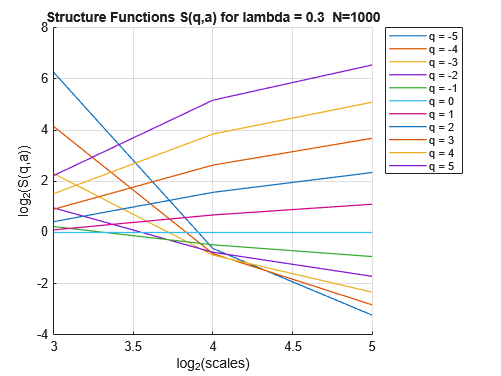

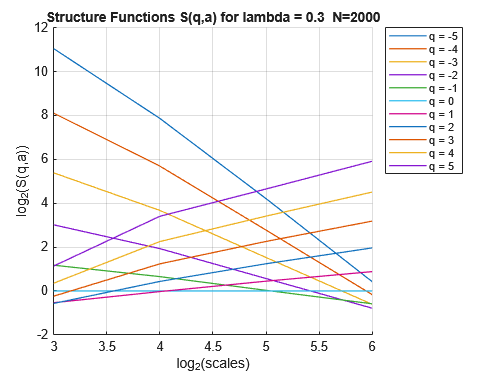

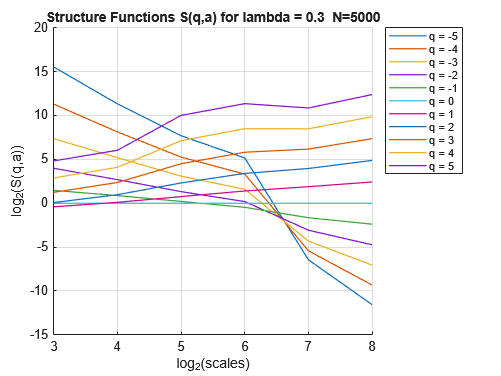

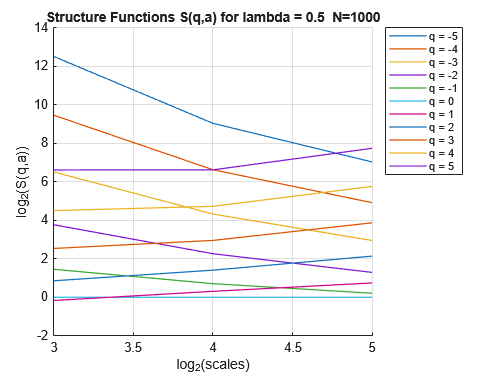

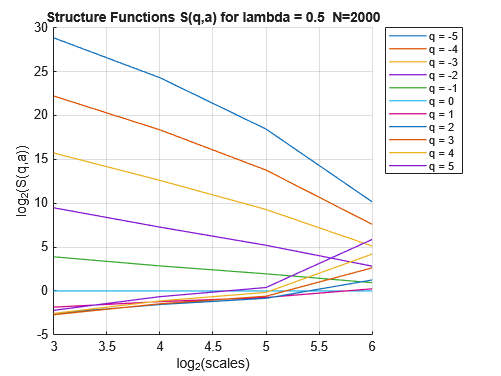

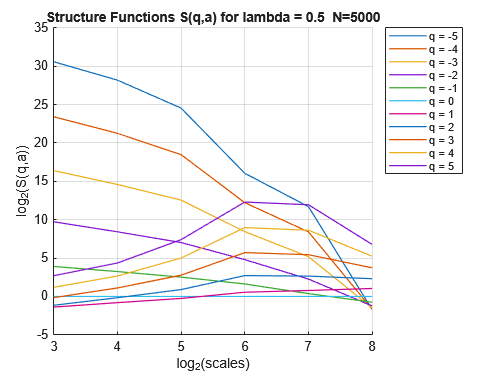

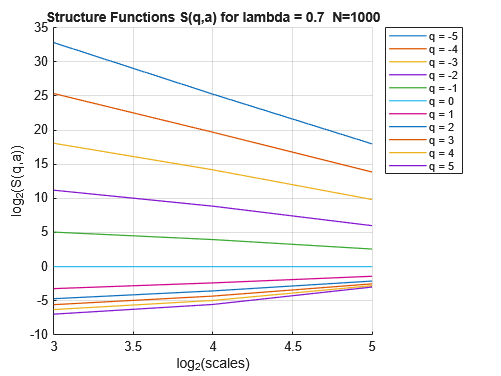

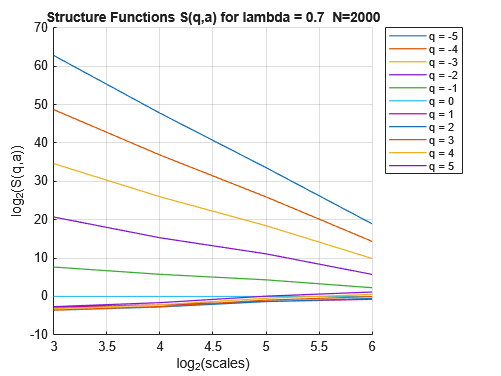


%% ---------------------------------------------------------
% 2. STRUCTURE FUNCTIONS S(q,a) (LOG–LOG) FOR EACH (H, N)
% Reads structfunc{hi,ni}.Tq and .logscales
% ---------------------------------------------------------

q_axis = linspace(-5, 5, 11);   % q values for WTMM structure functions

for hi = 1:numH
    for ni = 1:numN
        S    = structfunc{hi,ni}.Tq(:, 1:11);      % structure functions for q=-5:5
        loga = structfunc{hi,ni}.logscales;        % log2(a)

        figure; hold on;
        plot(loga, S(:,:), 'LineWidth', 1.0)
        

        % Legend labels: "a = scale_value"
        legendStrings = "q = " + string(round(q_axis, 3));
        legend(legendStrings, "Location", "bestoutside")

        xlabel("log_2(scales)")
        ylabel("log_2(S(q,a))")
        title("Structure Functions S(q,a) for lambda = " + string(lambda(hi))+ ...
              "  N="+string(Nvals(ni)))
        grid on
    end
end

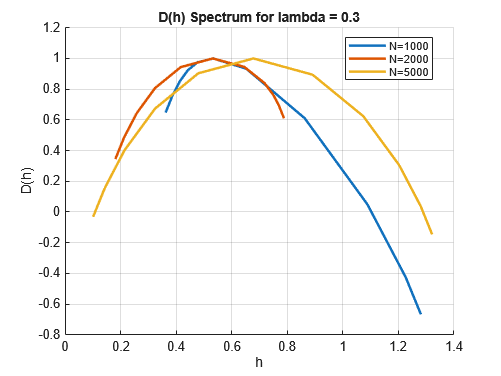

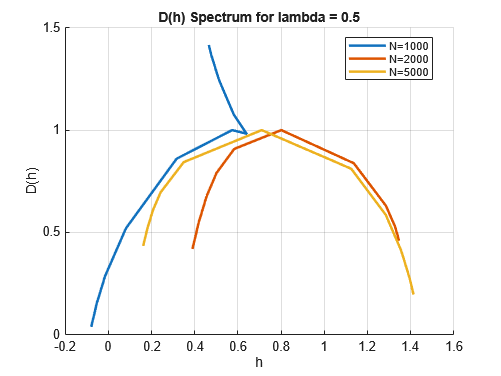

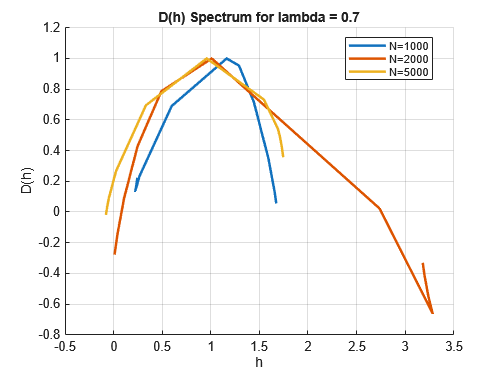


%% ---------------------------------------------------------
% 2. MULTIFRACTAL SPECTRUM D(h) VS NOISE LENGTH (PER H)
% ---------------------------------------------------------
for hi = 1:numH
    figure; hold on;
    for ni = 1:numN
        plot(h{hi,ni}, dh{hi,ni}, 'LineWidth', 2, 'Color', colorsN(ni,:));
    end
    xlabel("h"); ylabel("D(h)")
    title("D(h) Spectrum for lambda = " + string(lambda(hi)))
    legend("N="+string(Nvals), "Location","Best")
    grid on
end

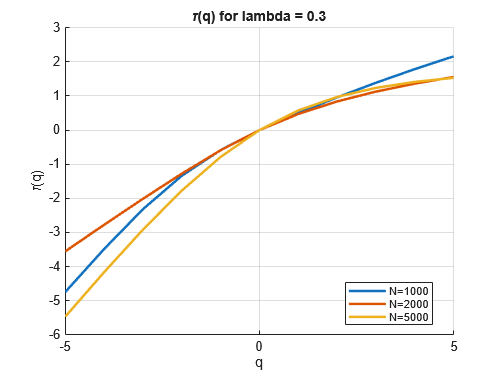

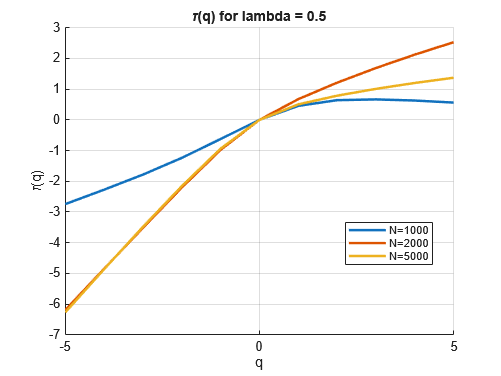

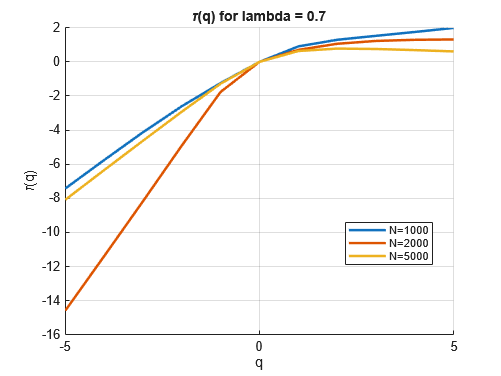


%% ---------------------------------------------------------
% 3. SCALING FUNCTION tau(q) VS NOISE LENGTH (PER H)
% ---------------------------------------------------------
for hi = 1:numH
    figure; hold on;
    for ni = 1:numN
        plot(qvals, tauq{hi,ni}, 'LineWidth', 2, 'Color', colorsN(ni,:));
    end
    xlabel("q"); ylabel("\tau(q)")
    title("\tau(q) for lambda = " + string(lambda(hi)))
    legend("N="+string(Nvals), "Location","Best")
    grid on
end

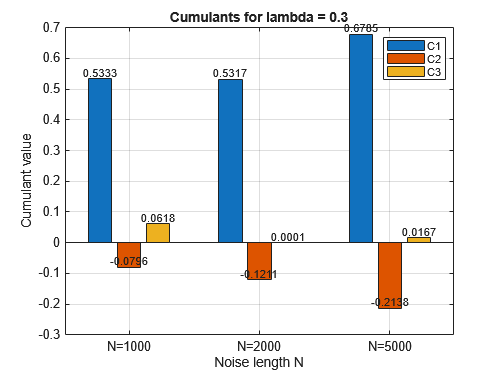

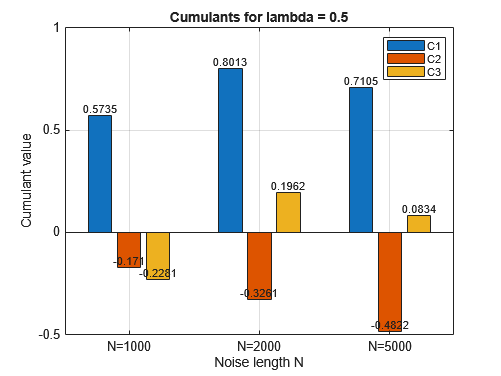

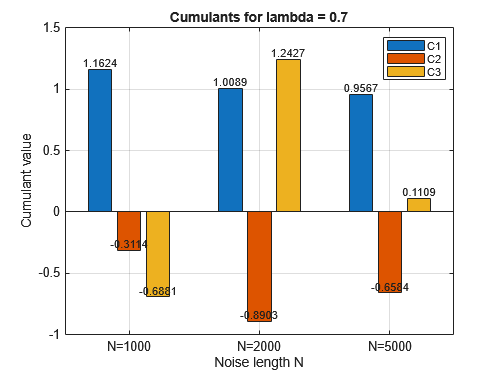


%% ---------------------------------------------------------
% 4. CUMULANTS VS NOISE LENGTH (PER H)
% Reads cp{hi,ni} only
% ---------------------------------------------------------
for hi = 1:numH
    Cmat = zeros(numN, 3);   % rows: N, cols: C1 C2 C3
    for ni = 1:numN
        Cmat(ni,:) = cp{hi,ni};
    end

    figure;
    b = bar(Cmat);
    set(gca, 'XTickLabel', "N="+string(Nvals))
    xlabel("Noise length N")
    ylabel("Cumulant value")
    legend("C1","C2","C3", "Location","Best")
    title("Cumulants for lambda = " + string(lambda(hi)))
    grid on

    % Optional: add labels above bars
    for k = 1:numel(b)
        x = b(k).XEndPoints;
        y = b(k).YEndPoints;
        labels = string(round(b(k).YData, 4));
        text(x, y, labels, ...
            'HorizontalAlignment','center', ...
            'VerticalAlignment','bottom', ...
            'FontSize', 9)
    end
end

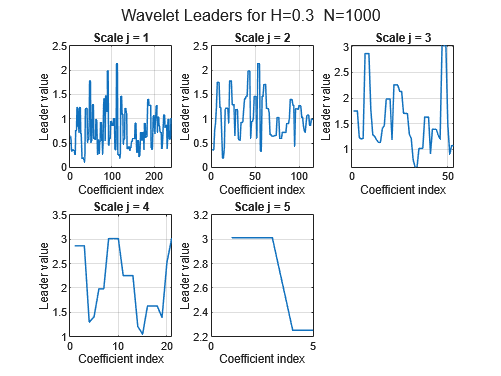

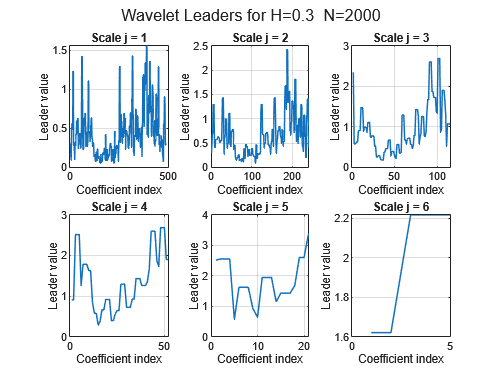

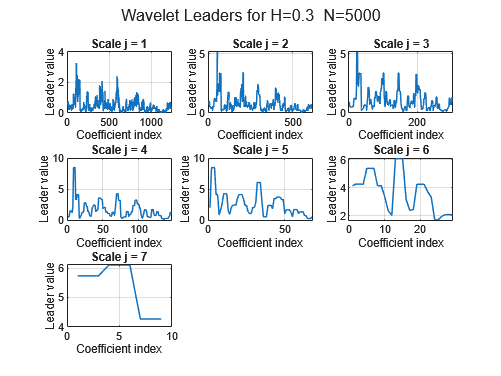

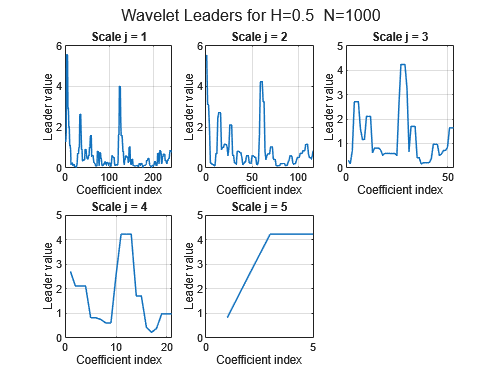

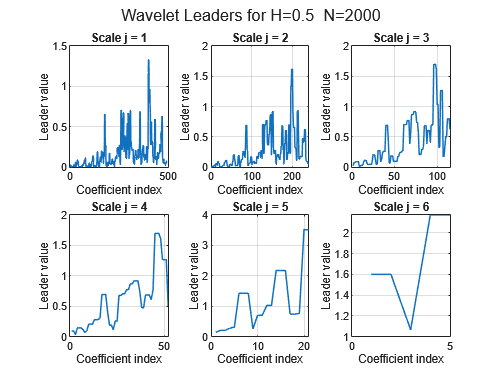

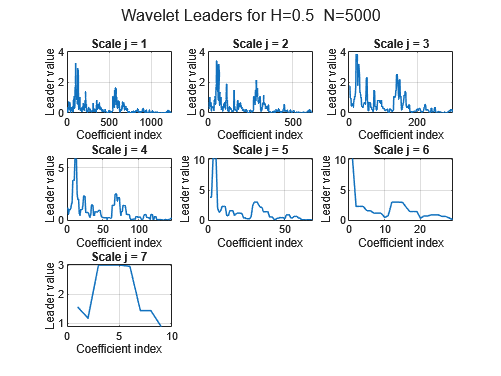

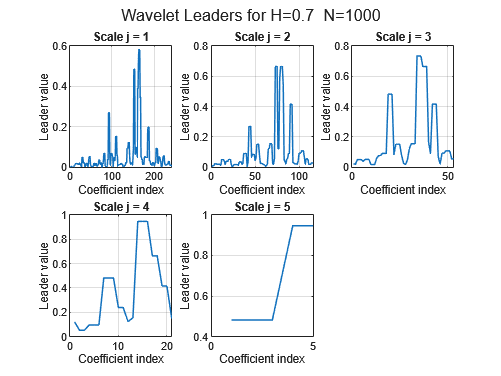

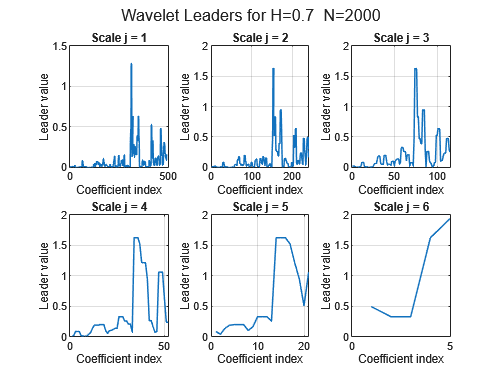



%% ---------------------------------------------------------
% 6. WAVELET LEADERS ACROSS SCALES (PER H, PER N)
% Reads leaders{hi,ni} only
% ---------------------------------------------------------
for hi = 1:numH
    for ni = 1:numN
        L = leaders{hi,ni};          % cell array of scales
        numL = numel(L);
        rows = ceil(numL/3);

        figure;
        for j = 1:numL
            subplot(rows, 3, j)
            plot(L{j}, 'LineWidth', 1.2)
            title("Scale j = " + string(j))
            xlabel("Coefficient index")
            ylabel("Leader value")
            grid on
        end
        sgtitle("Wavelet Leaders for H="+string(lambda(hi))+ ...
                "  N="+string(Nvals(ni)))
    end
end